**Project 1: Numerical simulation of a model neuron**

Tasks:

1. Description of a neuron, numerical simulation of a model neuron: solving the system of differential equations using the Runge Kutta 4th order method, analyzing the correctness of choosing the time step.

%Functions_executions(time, timestep,[a,b,c,d,I], type of dunamics)
%regular spiking
[f_RS,dfdt_RS]=Functions_Executions(200,0.01,[0.02,0.2,-65,8,10],1);
%Intrinsically bursting
[f_IB,dfdt_IB]=Functions_Executions(200,0.001,[0.02,0.2,-55,4,10],2);
%chattering
[f_CH,dfdt_CH]=Functions_Executions(200,0.001,[0.02,0.2,-50,2,10],3);
%fast spiking
[f_FS,dfdt_FS]=Functions_Executions(200,0.001,[0.1,0.2,-65,2,10],4);
%Low-threshold spiking
[f_LTS,dfdt_LTS]=Functions_Executions(200,0.001,[0.02,0.25,-65,2,10],5);
%Thalamo-cortical
[f_TC,dfdt_TC]=Functions_Executions(200,0.001,[0.02,0.25,-65,0.05,10],6);
%rezonator
[f_RZ,dfdt_RZ]=Functions_Executions(200,0.001,[0.1,0.26,-65,2,10],7);

2. Analyzing different regimes of a neuron dynamics, plotting time series and phase portraits of the signal, calculation of a regime map.

t=200;
dt=0.5;

a=0.2;
b=0.1;
c=-55;
d=4;
I=10;
D=0.5

v0=c;
u0=b*v0;
f0=[v0,u0];
const=[a,b,c,d,I];

fun=@Izhikevich_Neuron_model;
add_func=@After_spike_reset;

[f,dfdt]=RungeKutta(t,dt,f0,const,fun,add_func);

3. Adding Gaussian noise to the system, solving the system of differential equations with noise, analyzing the influence of noise amplitude on the system dynamics.

[f_RS,dfdt_RS]=Functions_Executions(1000,0.01,[0.02,0.2,-65,8,10,1],1);

4. Adding the coupling between 2 neurons, analyzing synchronization between neurons for different values of the coupling strength.

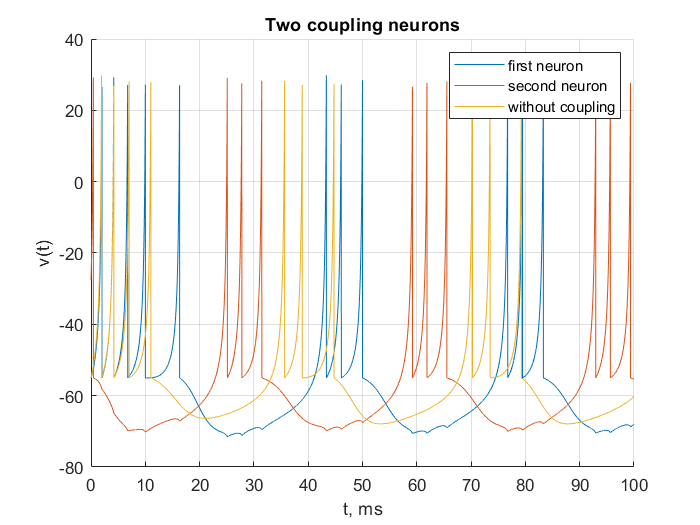

t=100;
dt=0.01;

a=0.03;
b=0.2;
c=-55;
d=2;
I=10;
D=0;
w=-0.05;

v0=c;
u0=b*v0;
f0=[v0,u0,v0/2,u0/2];
const=[a,b,c,d,I,D,w];

fun=@Izhikevich_Neuron_model_with_coupling;
add_func=@After_spike_reset;

[f,dfdt]=RungeKutta(t,dt,f0,const,fun,add_func);

[f_c,dfdt_c]=RungeKutta(t,dt,[v0,u0],const,@Izhikevich_Neuron_model,add_func);
Visualization(f(:,1),[f(:,2),f(:,4),f_c(:,2)],"t, ms","v(t)","Two coupling neurons",[],[],["first neuron", "second neuron", "without coupling"])

5. Simulation of a neural network with global topology, analyzing the influence of external stimulus and noise amplitude by calculating characteristic correlation time.